## 实验三 空间域滤波

### 平滑空间滤波

1. 读入图像并加入噪声

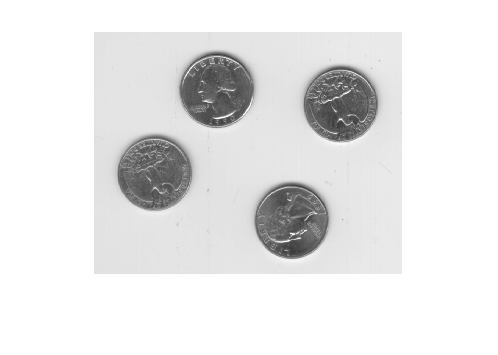

% 读取原图（标准化）
origin_std = im2double(imread("eight.tif"));
figure('Name','原图','NumberTitle','off');
imshow(origin_std);

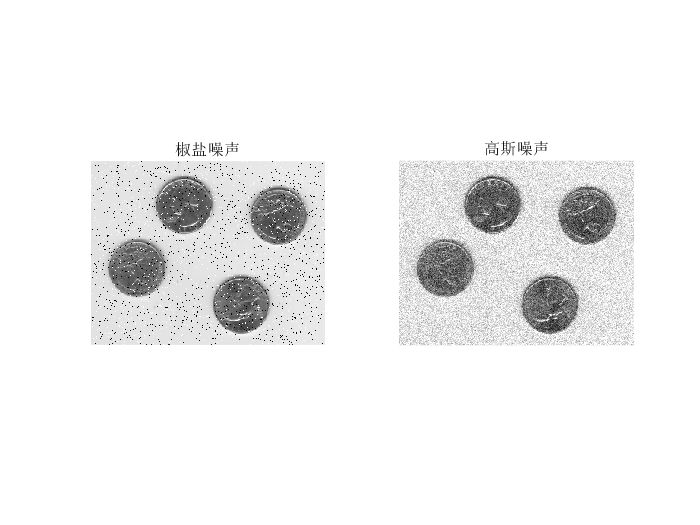

% 加入噪声
jiaoyan = imnoise(origin_std, "salt & pepper");
gaosi = imnoise(origin_std, "gaussian");

% 显示加入噪声后的图像
figure('Name','加入噪声','NumberTitle','off');
subplot(1, 2, 1);
imshow(jiaoyan); title('椒盐噪声');
subplot(1, 2, 2);
imshow(gaosi); title('高斯噪声');

2. 尝试使用不同的平滑模板（卷积核）

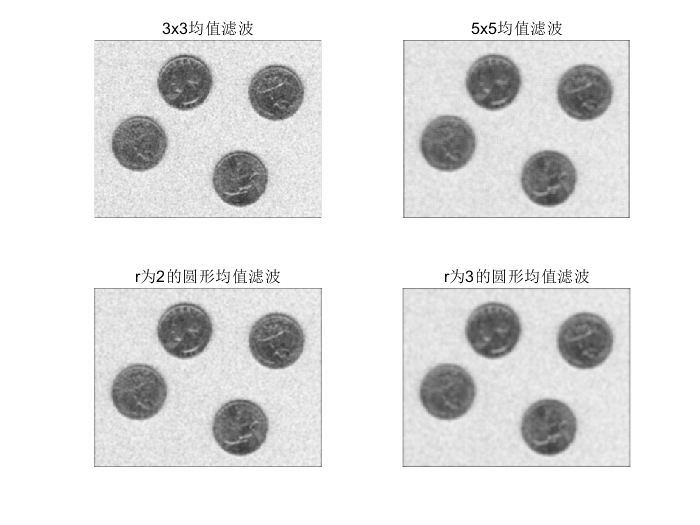

% 3x3均值滤波
avg3x3 = fspecial('average', 3);
% 5x5均值滤波
avg5x5 = fspecial('average', 5);

% r为2的圆形均值滤波
round2 = fspecial('disk', 2);
% r为3的圆形均值滤波
round3 = fspecial('disk', 3);

% 显示处理高斯噪声的结果
figure('Name','均值滤波处理高斯噪声','NumberTitle','off');
subplot(2, 2, 1);
imshow(imfilter(gaosi, avg3x3)); title('3x3均值滤波');
subplot(2, 2, 2);
imshow(imfilter(gaosi, avg5x5)); title('5x5均值滤波');
subplot(2, 2, 3);
imshow(imfilter(gaosi, round2)); title('r为2的圆形均值滤波');
subplot(2, 2, 4);
imshow(imfilter(gaosi, round3)); title('r为3的圆形均值滤波');

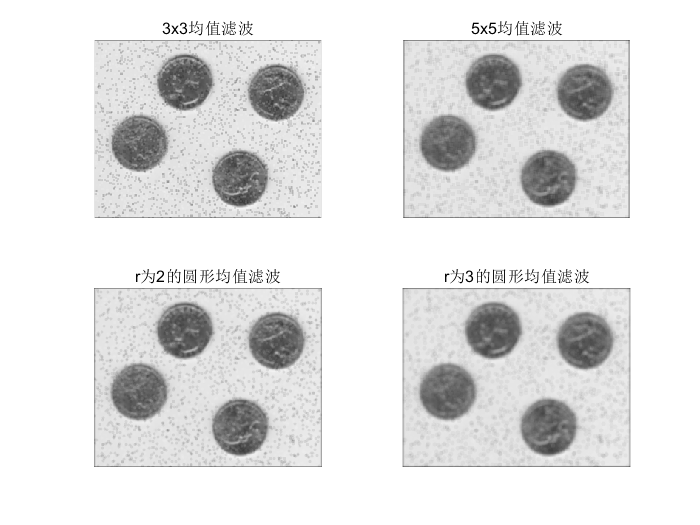


% 显示处理椒盐噪声的结果
figure('Name','均值滤波处理椒盐噪声','NumberTitle','off');
subplot(2, 2, 1);
imshow(imfilter(jiaoyan, avg3x3)); title('3x3均值滤波');
subplot(2, 2, 2);
imshow(imfilter(jiaoyan, avg5x5)); title('5x5均值滤波');
subplot(2, 2, 3);
imshow(imfilter(jiaoyan, round2)); title('r为2的圆形均值滤波');
subplot(2, 2, 4);
imshow(imfilter(jiaoyan, round3)); title('r为3的圆形均值滤波');

3. 使用不同的边界选项进行3x3均值滤波处理高斯噪声

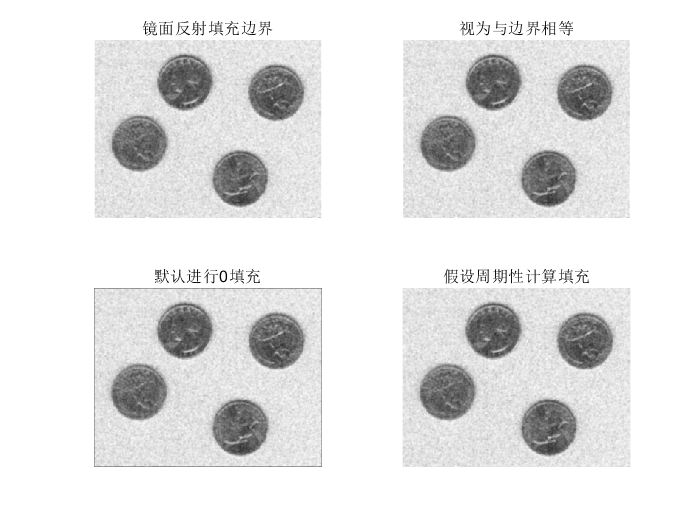

figure('Name','不同边界选项','NumberTitle','off');
subplot(2, 2, 1);
imshow(imfilter(gaosi, avg3x3, 'symmetric')); title('镜面反射填充边界');
subplot(2, 2, 2);
imshow(imfilter(gaosi, avg3x3, 'replicate')); title('视为与边界相等');
subplot(2, 2, 3);
imshow(imfilter(gaosi, avg3x3)); title('默认进行0填充');
subplot(2, 2, 4);
imshow(imfilter(gaosi, avg3x3, 'circular')); title('假设周期性计算填充');

4. 分别使用中值滤波和均值滤波处理椒盐噪声

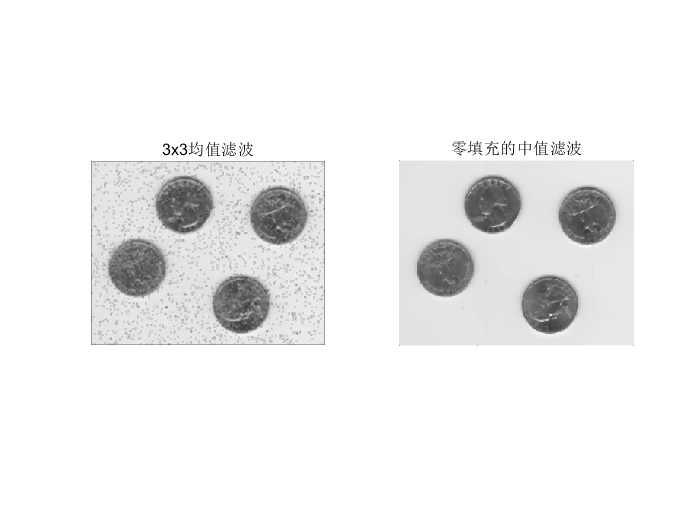

figure('Name','两种滤波方式处理椒盐噪声','NumberTitle','off');
subplot(1, 2, 1);
imshow(imfilter(jiaoyan, avg3x3)); title('3x3均值滤波');
subplot(1, 2, 2);
imshow(medfilt2(jiaoyan)); title('零填充的中值滤波');

5. 自行设计平滑空间滤波器

此处使用一个十字形的5*5大小的卷积核，采用均值滤波的思路

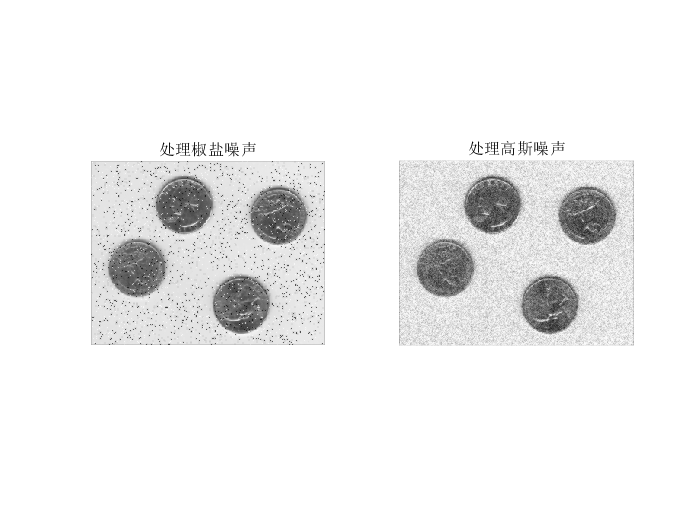

core = [0.05 0.05 0.05;
        0.05 0.6  0.05 ;
        0.05 0.05 0.05];
figure('Name','自行设计滤波器处理噪声','NumberTitle','off');
subplot(1, 2, 1);
imshow(imfilter(jiaoyan, core)); title('处理椒盐噪声');
subplot(1, 2, 2);
imshow(imfilter(gaosi, core)); title('处理高斯噪声');

### 锐化空间滤波

1. 使用3x3拉普拉斯算子进行滤波锐化增强

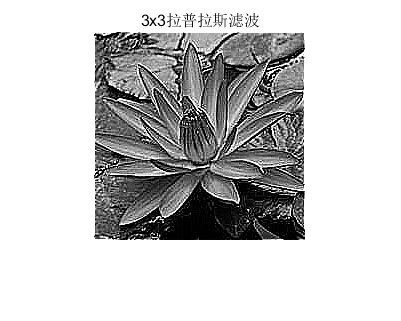

% 使用荷花图
flower_std = im2double(imread("flower.png"));
% 要用的拉普拉斯算子
lap = [1 1  1;
       1 -8 1;
       1 1  1];
figure('Name','3x3拉普拉斯滤波结果','NumberTitle','off');
% 此处注意需要对拉普拉斯算子取反，以得到拉普拉斯锐化模板
imshow(imfilter(flower_std, -lap)+flower_std); title('3x3拉普拉斯滤波');

2. 自定义函数genlaplacian用于生成奇数尺寸整数拉普拉斯算子

下面的w都是拉普拉斯锐化模板，即-(▽^2)

w1 = -genlaplacian(5);
w2 = -genlaplacian(9);
w3 = -genlaplacian(15);
w4 = -genlaplacian(25);

3. 采用5x5、9x9、15x15、25x25的拉普拉斯锐化模板先得到边缘图像

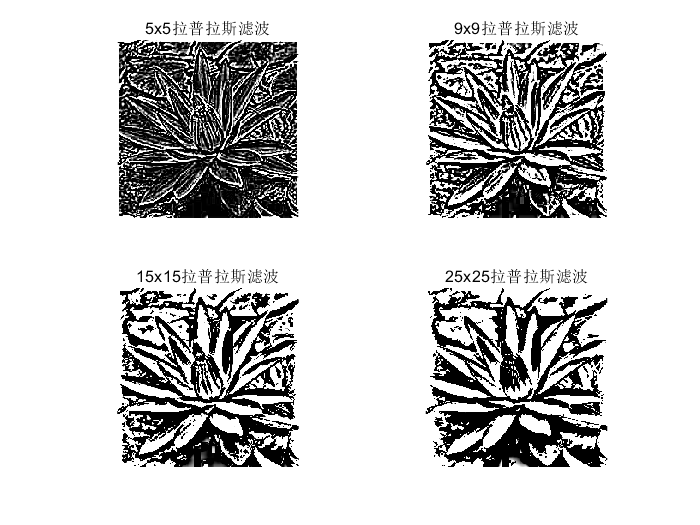

figure('Name','不同大小拉普拉斯滤波得到的边缘','NumberTitle','off');
subplot(2, 2, 1);
% 先得到边缘图像
wf1 = imfilter(flower_std, w1);
imshow(wf1); title('5x5拉普拉斯滤波');
subplot(2, 2, 2);
wf2 = imfilter(flower_std, w2);
imshow(wf2); title('9x9拉普拉斯滤波');
subplot(2, 2, 3);
wf3 = imfilter(flower_std, w3);
imshow(wf3); title('15x15拉普拉斯滤波');
subplot(2, 2, 4);
wf4 = imfilter(flower_std, w4);
imshow(wf4); title('25x25拉普拉斯滤波');

4. 边缘图像与原图叠加

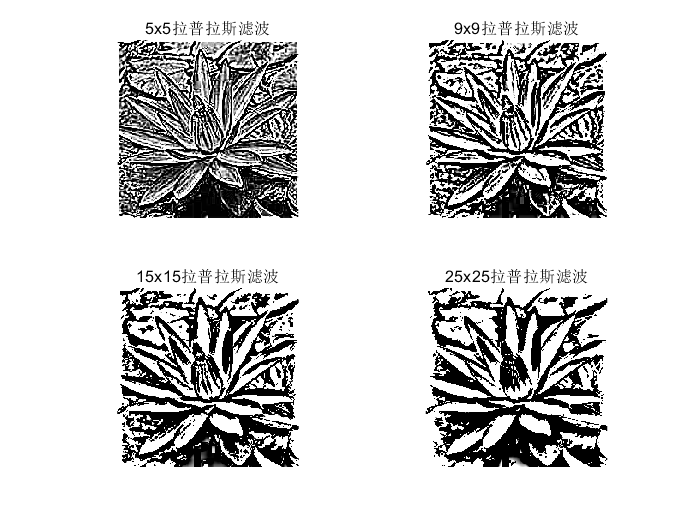

figure('Name','不同大小拉普拉斯锐化模板的增强结果','NumberTitle','off');
subplot(2, 2, 1);
% 叠加上原图以展示最后结果
imshow(flower_std+wf1); title('5x5拉普拉斯滤波');
subplot(2, 2, 2);
imshow(flower_std+wf2); title('9x9拉普拉斯滤波');
subplot(2, 2, 3);
imshow(flower_std+wf3); title('15x15拉普拉斯滤波');
subplot(2, 2, 4);
imshow(flower_std+wf4); title('25x25拉普拉斯滤波');

附加1：尝试使用中值滤波去噪后再使用拉普拉斯锐化模板进行增强

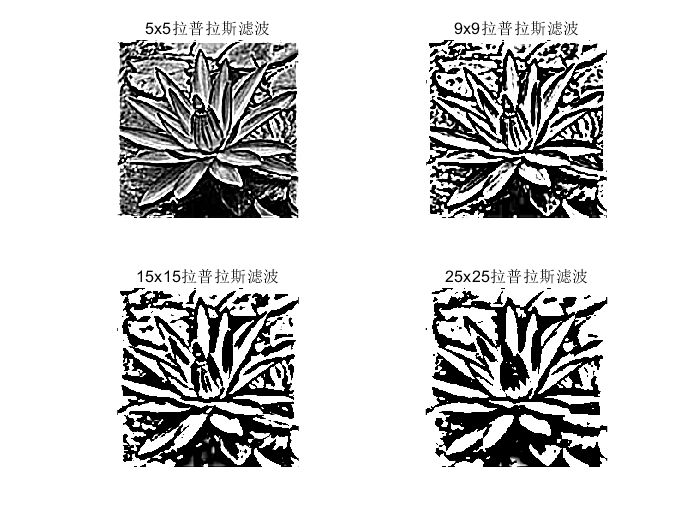

dec_flower = imfilter(flower_std, fspecial('average', 3));
wf1 = imfilter(dec_flower, w1);
wf2 = imfilter(dec_flower, w2);
wf3 = imfilter(dec_flower, w3);
wf4 = imfilter(dec_flower, w4);

figure('Name','先进行均值滤波去噪的增强结果','NumberTitle','off');
subplot(2, 2, 1);
imshow(dec_flower+wf1); title('5x5拉普拉斯滤波');
subplot(2, 2, 2);
imshow(dec_flower+wf2); title('9x9拉普拉斯滤波');
subplot(2, 2, 3);
imshow(dec_flower+wf3); title('15x15拉普拉斯滤波');
subplot(2, 2, 4);
imshow(dec_flower+wf4); title('25x25拉普拉斯滤波');

附加2：尝试使用不同的边缘提取算子进行锐化增强

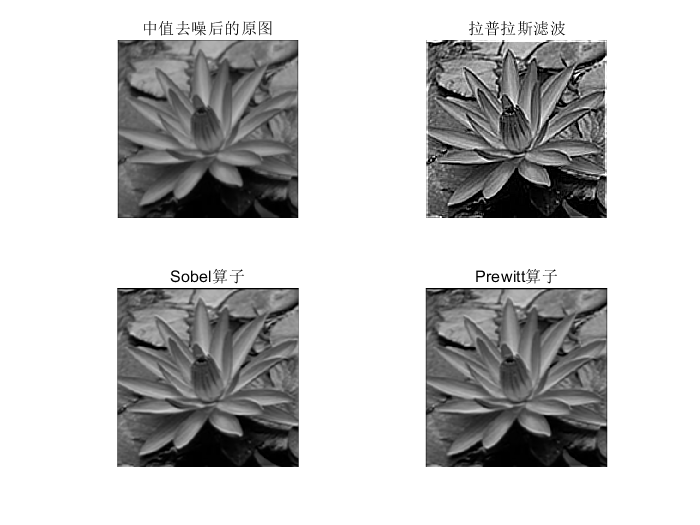

sob = fspecial('sobel')/4;
prew = fspecial('prewitt')/3;

figure('Name','3x3均值滤波后使用不同边缘提取算子叠加','NumberTitle','off');
subplot(2, 2, 1);
imshow(dec_flower); title('中值去噪后的原图');
subplot(2, 2, 2);
imshow(imfilter(dec_flower, -lap)+dec_flower); title('拉普拉斯滤波');
subplot(2, 2, 3);
imshow(imfilter(dec_flower, sob)+dec_flower); title('Sobel算子')
subplot(2, 2, 4);
imshow(imfilter(dec_flower, prew)+dec_flower); title('Prewitt算子')

用于生成奇数nxn大小的拉普拉斯算子

function laplacian_core = genlaplacian(n)
    error = MException("myComponent:inputError", '参数不能为偶数');
    if (rem(n, 2) == 0)
        laplacian_core = nan;
        throw(error);
    end
    laplacian_core = ones(n, n);
    laplacian_core(ceil(n/2), ceil(n/2)) = -n*n+1;
end